# Applying the PINES to new test data

The PINES weight map is **Rating_Weights_LOSO_2.nii** in the repository.

If you have the CanlabCore repository from Github on your Matlab path, 

an easy way to apply the signature pattern to a new dataset is the

**apply_mask()**

method for fmri_data objects.  For example, this code will load a sample dataset 

and apply the PINES. It returns a vector of one PINES response per input image.


test_images = load_image_set('emotionreg');                 % Load 30 emotion regulation-related contrast maps from Wager et al. 2008, Neuron

Defaults settings have been modified by file(s):
  /Users/f003vz1/Dropbox (Dartmouth College)/Matlab_code_external/spm12/spm_my_defaults.m
Modified fields: stats 
Defaults settings have been modified by file(s):
  /Users/f003vz1/Dropbox (Dartmouth College)/Matlab_code_external/spm12/spm_my_defaults.m
Modified fields: stats 
Loaded images:
/Users/f003vz1/Documents/GitHub/CanlabCore/CanlabCore/Sample_datasets/Wager_et_al_2008_Neuron_EmotionReg/Wager_2008_emo_reg_vs_look_neg_contrast_images.nii
/Users/f003vz1/Documents/GitHub/CanlabCore/CanlabCore/Sample_datasets/Wager_et_al_2008_Neuron_EmotionReg/Wager_2008_emo_reg_vs_look_neg_contrast_images.nii
/Users/f003vz1/Documents/GitHub/CanlabCore/CanlabCore/Sample_datasets/Wager_et_al_2008_Neuron_EmotionReg/Wager_2008_emo_reg_vs_look_neg_contrast_images.nii
/Users/f003vz1/Documents/GitHub/CanlabCore/CanlabCore/Sample_datasets/Wager_et_al_2008_Neuron_EmotionReg/Wager_2008_emo_reg_vs_look_neg_contrast_images.nii
/Users/f003vz1/Documents/GitHub/Can


pines_sig = fmri_data(which('Rating_Weights_LOSO_2.nii'));  % Load the PINES map as an fmri_data object

Using default mask: /Users/f003vz1/Documents/GitHub/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
Defaults settings have been modified by file(s):
  /Users/f003vz1/Dropbox (Dartmouth College)/Matlab_code_external/spm12/spm_my_defaults.m
Modified fields: stats 
Defaults settings have been modified by file(s):
  /Users/f003vz1/Dropbox (Dartmouth College)/Matlab_code_external/spm12/spm_my_defaults.m
Modified fields: stats 
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 971812 bytes
Loading image number:     1
Elapsed time is 0.025628 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 236735  Bit rate: 17.85 bits



pines_response = apply_mask(test_images, pines_sig, 'pattern_expression'); % Apply the weight map

Number of zero or NaN values within weight mask, by input image:
  0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0  43   0   1   0   0   0   0   0   0   0   0 


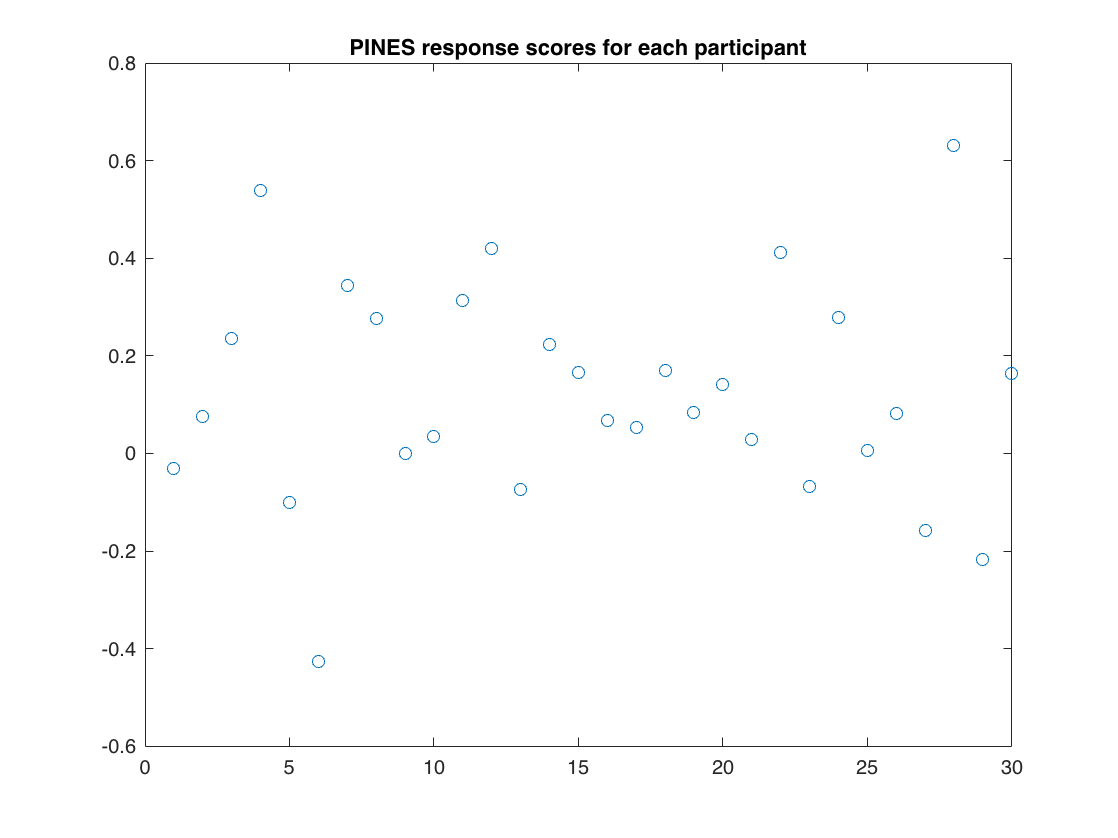


figure; plot(pines_response, 'o'); title('PINES response scores for each participant');

See also:  

**canlab_pattern_similarity()**

With the Neuroimaging_Pattern_Masks repository, you can load the PINES sigature this way as well:

pines = load_image_set('pines');

Defaults settings have been modified by file(s):
  /Users/f003vz1/Dropbox (Dartmouth College)/Matlab_code_external/spm12/spm_my_defaults.m
Modified fields: stats 
Loaded images:
/Users/f003vz1/Documents/GitHub/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2015_Chang_PLoSBiology_PINES/Rating_Weights_LOSO_2.nii


### Notes on masking and similarity metrics

The PINES was trained using a more liberal mask that included the whole brain and a bit of a border around it. The logic was to be more inclusive and make sure not to miss gray-matter voxels around the edge of the brain. Since then, our tools use a more restrictive brain mask when loading images, called brainmask_canlab.nii. (This is a standard mask, but there may be older versions of brainmask.nii that are slightly different. So we specify the “canlab” one in the name to avoid ambiguity.)

When you apply the PINES to test images, you will get slightly different responses depending on which voxels are included in the data images you’re applying it to, whether you’re using a mask, and which similarity metric you’re using (generally, dot product, cosine similarity, or correlation). 

For example, if you’re using the dot product to calculate pattern expression and your data are masked to include only in-brain voxels (e.g., with brainmask_canlab.nii) or only gray-matter voxels (e.g., with gray_matter_mask.nii in the CANlab toolbox), only the weights that have in-mask data values will be used when you take the dot product of the weights and the images. Any weights that don’t have non-zero values in the test image, or image values that don’t have corresponding weights, will not influence the dot product.

If you are using a cosine similarity metric to calculate pattern expression, the scaling of the overall response will change depending on whether you mask the PINES (or other weight map) to match the space of the images, but the relative values will be the same, as long as you use the same masking consistently for all individuals.

If you are using a correlation similarity metric to calculate pattern expression, the responses could differ depending on whether you treat zeros as numerical data or treat zeros as invalid/missing values and exclude them. That is the convention adopted by SPM and many other toolboxes, including CANlab tools. In this case, you have to exclude missing values (including 0s) and calculate correlations on voxels with valid values for both the weight image and the test data image.

The function canlab_pattern_similarity.m attempts to handle these cases in a consistent manner, treating voxels with values of 0 as missing data where applicable.

help canlab_pattern_similarity

  Calculate similarity between each column in a data matrix dat and a vector of pattern weights
 
  - Similarity options: dot product, cosine similarity, and correlation
  - Columns are often images, e.g., from fmri_data.dat for fmri_data objects
  - weights are pattern weights from one or more 'signature' patterns (each pattern is a column)
 
  - Assumes dat and pattern_weights matrices have equal rows (voxels) and include valid voxels
  - Removes empty column data column-wise (image-wise) in case some images have uneven voxel coverage
 
  - Used in apply_mask, extract_roi_averages, image_similarity_plot***
 
  similarity_output = canlab_pattern_similarity(dat, pattern_weights)
 
  :Inputs:
    **dat**  voxels x images matrix of data to compare to patterns
 
    **pattern_weights** voxels x images matrix of patterns to compare to data
 
  :Optional Inputs:
 
    **dot_product**
        [Default] Use dot product
 
    **cosine_similarity**
        Use cosine similarity